## cse327hw8 Q3

Zian Shang

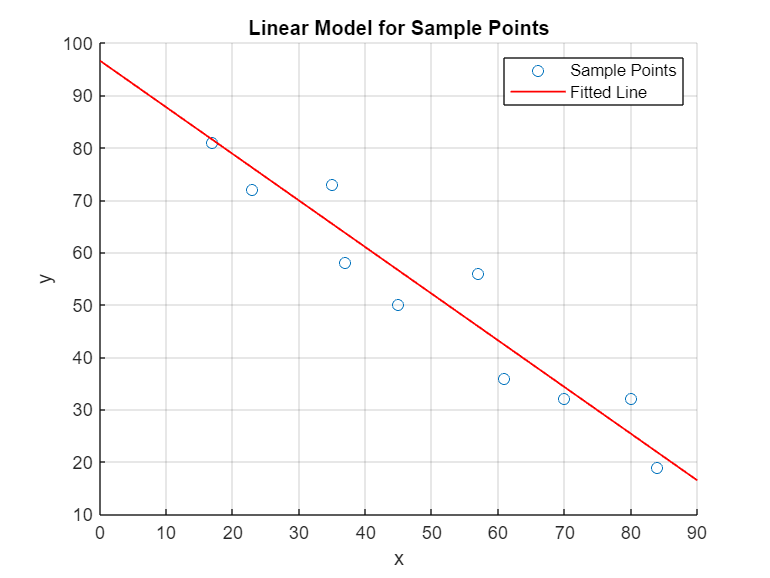

% Set 10 sample points
pts = [17 23 35 37 45 57 61 70 80 84;
        81 72 73 58 50 56 36 32 32 19];

% Extract x and y values
x = pts(1, :);
y = pts(2, :);

% Get N sample points
N = length(x);

% Calculate matrix entry values
x_square = x.^2;
y_square = y.^2;
xy = x.*y;

A = [sum(x_square), sum(xy), sum(x);
     sum(xy), sum(y_square), sum(y);
     sum(x), sum(y), N];

[U, D, V] = svd(A);

% Extract eigenvalues from the diagonal of D
lambda = diag(D);

% Get eigenvalue indices
[~, index] = min(abs(lambda));

% Extract corresponding eigenvector
h = V(:, index);

% Normalize eigenvector
h = h / norm(h);

% Extract a, b, and c from the eigenvector
a = h(1);
b = h(2);
c = h(3);

% Generate predicted values
x_values = linspace(0, 90, 10);
y_values = (-a*x_values- c) / b;

% Plot points and the fitted line
figure;
scatter(x, y, 'DisplayName', 'Sample Points');
hold on;

plot(x_values, y_values, '-r', 'LineWidth', 1, 'DisplayName', 'Fitted Line');
title('Linear Model for Sample Points');
xlabel('x');
ylabel('y');
legend('show');
grid on;

hold off;